Clase 4

# Modelado el elemento base (eslabón)

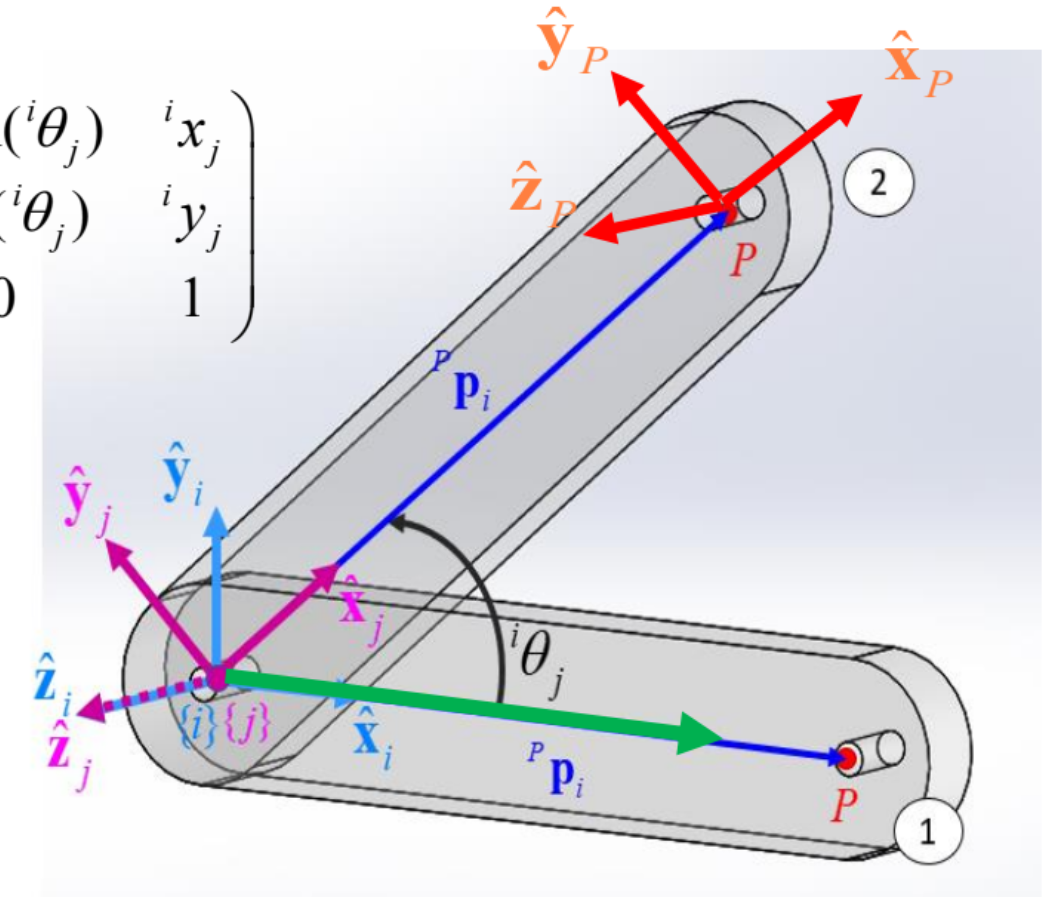

Mode lado de un eslabón

% Plantemiento de las funciones

syms T_i_j(x_i_j, y_i_j, theta_i_j)

T_i_j(x_i_j, y_i_j, theta_i_j) = [cos(theta_i_j),-sin(theta_i_j),0,x_i_j;sin(theta_i_j),cos(theta_i_j),0,y_i_j;0,0,1,0;0,0,0,1]

$$T\_i\_j(x\_i\_j, y\_i\_j, theta\_i\_j) = \left(\begin{array}{cccc} \cos\left(\theta_{i,j}\right) & -\sin\left(\theta_{i,j}\right) & 0 & x_{i,j}\\ \sin\left(\theta_{i,j}\right) & \cos\left(\theta_{i,j}\right) & 0 & y_{i,j}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Calculo de la posición del sistema P

syms theta_i_j_c x_j_P

T_i_j_c = T_i_j(0, 0, theta_i_j_c)

$$T\_i\_j\_c = \left(\begin{array}{cccc} \cos\left(\theta_{i,j,c}\right) & -\sin\left(\theta_{i,j,c}\right) & 0 & 0\\ \sin\left(\theta_{i,j,c}\right) & \cos\left(\theta_{i,j,c}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_j_P = T_i_j(x_j_P, 0, 0)

$$T\_j\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{j,P}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_i_P = T_i_j_c*T_j_P

$$T\_i\_P = \left(\begin{array}{cccc} \cos\left(\theta_{i,j,c}\right) & -\sin\left(\theta_{i,j,c}\right) & 0 & x_{j,P}\,\cos\left(\theta_{i,j,c}\right)\\ \sin\left(\theta_{i,j,c}\right) & \cos\left(\theta_{i,j,c}\right) & 0 & x_{j,P}\,\sin\left(\theta_{i,j,c}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$